1.MUA的处理

MUA记录的应该是每个时间点下面spike的数量

有两个cell是因为降采样与之不同，简单来讲，第二个记录的spike更少，一般采用第二个

clear;
load('D:\Desktop\Ensemble coding\data\datanum.mat')


%这两个是选数据日期的，只要改第二位就行，一共四个
name = a{1,9};
time = a{2,9};
path = sprintf('D:\\Desktop\\Ensemble coding\\data\\%sdata',time);%数据存储路径

%这个是用来数据种类的
block = 'EC';
type = 0; % EC=0,SC=1,patch=2(0815的patch用14

%下面的应该不需要改
num = datanum.(sprintf('data%s',time)).(block);

% 导入数据
[~, stimres, stimIDs, MUAs] = load_matrix(num, name, path);

% 进行id回溯
[stimIDs_new] = real_sequence(num, stimres, stimIDs, type);

% 分组为trb
[cluster,cluster_data] = clusterdata(num, stimIDs_new, MUAs, type, name);



%fft
i=0;
for session  = num
    i = i+1;
    for coil = 1:96
        mua(i,coil,:) = squeeze(mean(cluster_data2.(sprintf('session%d',session)).(sprintf('coil%d',coil)).target1(:,420:1440),1));
    end
end
muamean = squeeze(mean(mua,1));



timeLimits = seconds([0 2.04]); % 秒
frequencyLimits = [0 250]; % Hz

muafft = [];
% 对感兴趣的信号时间区域进行索引
a_ROI = muamean';
sampleRate = 500; % Hz
startTime = 0; % 秒
timeValues = startTime + (0:length(a_ROI)-1).'/sampleRate;
a_ROI = timetable(seconds(timeValues(:)),a_ROI,'VariableNames',{'Data'});
a_ROI = a_ROI(timerange(timeLimits(1),timeLimits(2),'closed'),1);
[Pa_ROI, Fa_ROI] = pspectrum(a_ROI, ...
    'FrequencyLimits',frequencyLimits);
m = 10*log(Pa_ROI);
%imagesc(Fa_ROI(1:500),1:96,m(1:500,:)')


2.分朝向汇总

timeLimits = seconds([0 2.04]); % 秒
frequencyLimits = [0 250]; % Hz
goodchan = [32,31,64,63,61,30,28,26,59,62,29,27,24,94,60,54,21,22,20,18,25,23,16,96,95]
max = 500;
figure(1);
sgtitle('MUA Orientation Tuning',FontSize=18);
for ori = 1:9
    
    mua = squeeze(mean(all_orient_data(:,420:1440,:,ori),1));

    muafft = [];
    % 对感兴趣的信号时间区域进行索引
    a_ROI = mua;
    sampleRate = 500; % Hz
    startTime = 0; % 秒
    timeValues = startTime + (0:length(a_ROI)-1).'/sampleRate;
    a_ROI = timetable(seconds(timeValues(:)),a_ROI,'VariableNames',{'Data'});
    a_ROI = a_ROI(timerange(timeLimits(1),timeLimits(2),'closed'),1);
    [Pa_ROI, Fa_ROI] = pspectrum(a_ROI, ...
        'FrequencyLimits',frequencyLimits);
    m = 10*log(Pa_ROI);
    subplot(3,3,ori)
    imagesc(Fa_ROI(1:max),1:96,m(1:max,:)');
    colormap('parula')
    yyaxis right
    a=plot(Fa_ROI(1:max),10*log(mean(Pa_ROI(1:max,:),2)))  %全通道
    a.Color = '#925EB0';
    a.LineWidth = 1.5;
    a.LineStyle = '-.';
    hold on
    b=plot(Fa_ROI(1:max),10*log(mean(Pa_ROI(1:max,goodchan),2)))  %好通道
    b.Color = '#4A5F7E';
    b.LineWidth = 1.5;
    b.LineStyle = '-';
    
    c=plot(Fa_ROI(1:max),10*log(mean(Pa_ROI(1:max,setdiff(1:96,goodchan)),2)))
    c.Color = 'red';
    c.LineWidth = 1.5;
    xline(6.25, ...
        LineStyle="--", ...
        Alpha=0.5, ...
        Color='k', ...
        DisplayName = 'f =6.25hz',...
        Label='f', ...
        LabelHorizontalAlignment='right', ...
        LabelVerticalAlignment='top', ...
        LabelOrientation = 'horizontal');
    xline(12.5, ...
        LineStyle="--", ...
        Alpha=0.5, ...
        Color='k', ...
        DisplayName = '2f =12.5hz',...
        Label='2f', ...
        LabelHorizontalAlignment='right', ...
        LabelVerticalAlignment='top', ...
        LabelOrientation = 'horizontal');

    xline(25, ...
        LineStyle="-", ...
        LineWidth= 1, ...
        Alpha=0.5, ...
        ...
        Color='k', ...
        Label='25hz', ...
        LabelHorizontalAlignment='right', ...
        LabelVerticalAlignment='top', ...
        LabelOrientation = 'horizontal');
    ylim([-160, -40])
    subtitle(sprintf('Target-Ori%d',ori*20-10),"FontSize",14)    
    hold off
end

legend('All','Non-ClusterA','ClusterA','f=6.25hz')

3.朝向tuning

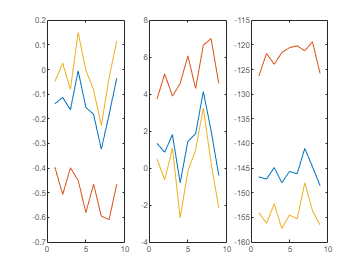

for ori = 1:9    
    mua = squeeze(mean(all_orient_data(:,420:1440,:,ori),1));
    % 对感兴趣的信号时间区域进行索引
    a_ROI = mua;
    sampleRate = 500; % Hz
    startTime = 0; % 秒
    timeValues = startTime + (0:length(a_ROI)-1).'/sampleRate;
    a_ROI = timetable(seconds(timeValues(:)),a_ROI,'VariableNames',{'Data'});
    a_ROI = a_ROI(timerange(timeLimits(1),timeLimits(2),'closed'),1);
    [Pa_ROI, Fa_ROI] = pspectrum(a_ROI, ...
        'FrequencyLimits',frequencyLimits);
    muatunig(:,:,ori) = 10*log(Pa_ROI);
end
%信噪比
radius = 20;
for ori = 1:9
    for coil = 1:96
        signal = muatunig(103,coil,ori);
        noise = mean(muatunig((103-radius):(103+radius),coil,ori),1);
        x(ori,coil,1) = 10*log(signal/noise);
        x(ori,coil,2) = signal-noise;
        x(ori,coil,3) = signal;
    end
end
goodchan1 = [32,31,64,63,61,30,28,26,59,62,29]
figure(2)
title('MUA Orientation Tuning',FontSize=20);
t = {'S/N','S-N','S'};
for i = 1:3
    subplot(3,1,i);
    plot(mean(x(:,:,i),2),Color='black',Marker='o',LineWidth=2);
    hold on 
    plot(mean(x(:,goodchan,i),2),Color='#7EA6D9',Marker='o',LineWidth=2);
    plot(mean(x(:,setdiff(1:96,goodchan),i),2),Color='red',Marker='o',LineWidth=2);
    plot(mean(x(:,goodchan1,i),2),Color='#4A5F7E',Marker='o',LineWidth=2);
    hold off
    subtitle(t{i})
    xticks([1,3,5,7,9]);
    xticklabels({'10','50','90','130','170'});
end

legend('All','Non-ClusterA','ClusterA','ClusterE')
